# Systematic review of SysID

## Part 0. Toy example - 2-DoF mass-spring-dampler system

Define stiffness and mass matrices

|\/\/\/\/\O\/\/\/\/\O

   k1 c1  m1  k2 c2  m2


$$M\ddot{X} +\textrm{C}\dot{X+} \textrm{KX}=F$$


clc;
clear;
close all;
m1=5; %mass 1 [kg]
m2=2; %mass 2 [kg]
k1=200; %spring 1 [N/m]
k2=100; %spring 2 [N/m]
c1=10; % damping coeff 1
c2=10; % damping coeff 2
M=[m1 0;0 m2]; %mass matrix
K=[k1+k2 -k2; -k2 k2]; %stiffness matrix
Damp=[c1+c2 -c2; -c2 c2]; % damping matrix

Create time-domain signal by differential equation


$$\left\lbrack \begin{array}{cc}
m_1  & 0\\
0 & m_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\ddot{x} }_1 \\
{\ddot{x} }_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
c_1 +c_2  & -c_2 \\
-c_2  & c_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\dot{x} }_1 \\
{\dot{x} }_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
k_1 +k_2  & -k_2 \\
{-k}_2  & k_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
F_1 \\
F_2 
\end{array}\right\rbrack$$


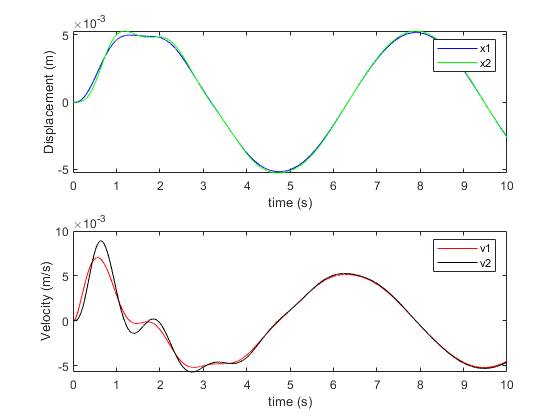

%% Solving system as ODE
T = 10;
nt = 10000;
tspan=linspace(0,T,nt);
y0=[0;0;0;0];
F = zeros(2,length(tspan));
F(1,:) = sin(1*tspan);
odefun=@(t,y) solve_2dof(t,y,M,Damp,K,tspan,F);
[tsol,ysol]=ode45(odefun,tspan,y0);
figure(1)
plot_dv(tsol,ysol)

Create time-domain signal by state-space model

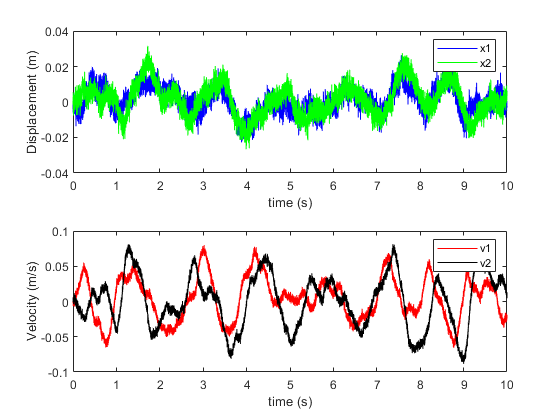

C = [1,0,0,0;
     0,1,0,0;
     0,0,1,0;
     0,0,0,1];
rng(1)
promu = [0;0;0;0];
prosi = 0.0000001*eye(4);
obsmu = [0;0;0;0];
obssi = 0.00001*eye(4);
ysol1 = glti_2dofO_generator(m1,m2,k1,k2,c1,c2,T,nt,y0,F,C,...
                                        promu,prosi,obsmu,obssi);
figure(2)
plot_dv(tspan,ysol1')

% save
csvwrite('2dof.csv',ysol1)

Calculate Frequency response function

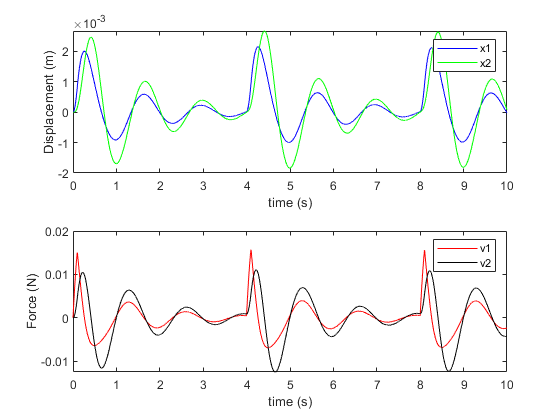

hammer = zeros(length(tspan),1);
hammer(1:100) = 1;
hammer(4000:4100) = 1;
hammer(8000:8100) = 1;
F = zeros(2,length(tspan));
F(1,:) = hammer;
odefun=@(t,y) solve_2dof(t,y,M,Damp,K,tspan,F);
[tsol,ysol]=ode45(odefun,tspan,y0);
figure(3)
plot_dv(tsol,ysol)
% figure(3)
% plot(tspan,hammer)
ylabel('Force (N)')

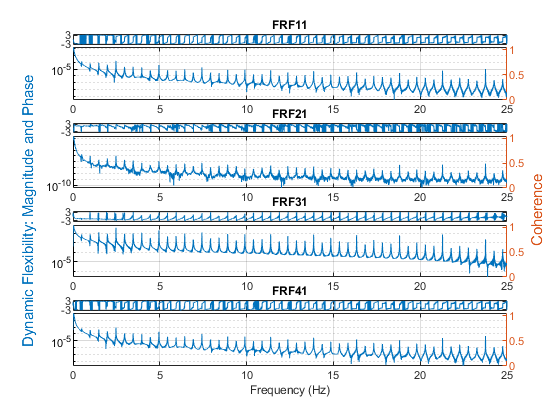

winlen = size(hammer,1);
figure(4)
modalfrf(hammer(:)',ysol(:,:),50,hann(winlen),0.5*winlen,'Sensor','dis');